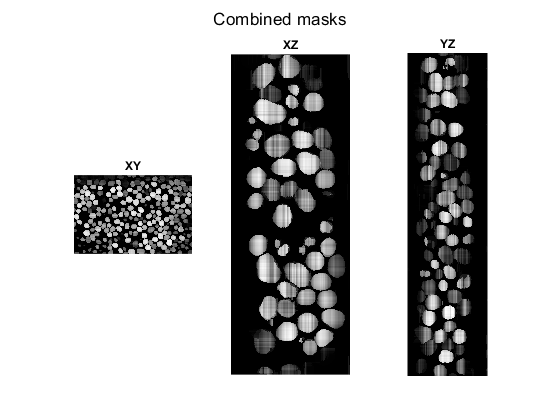

clear;clc;

nx = 1324;
ny = 1985;
nz = 492;

% read the combined segmentation labels from per view for a rough
% impression about current results
parfor i=1:nz
    img = imread(['combine/slice_' num2str(i-1,'%05d') '.tif']);
    Images(:,:,i)=img;
end

figure; subplot(1,3,1); imshow(Images(:,:,100),[]); title('XY')
subplot(1,3,2); imshow(squeeze(Images(:,100,:)),[]); title('XZ')
subplot(1,3,3); imshow(squeeze(Images(100,:,:)),[]); title('YZ')
sgtitle('Combined masks')

Probability map

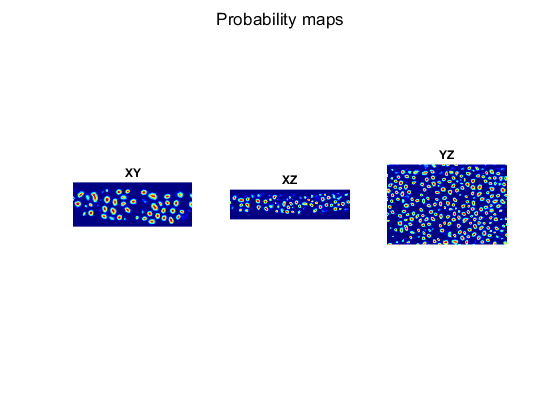

%% Read probability maps
% xz
parfor i=1:ny
    slice = imread(['prob/xz/slice_' num2str(i-1,'%05d') '.tif']);
    slice = imresize(slice, [nz nx]);
    StackXY(:,:,i) = slice;
end
% xy
parfor i=1:nx
    slice = imread(['prob/xy/slice_' num2str(i-1,'%05d') '.tif']);
    slice = imresize(slice, [nz ny]);
    StackXZ(:,:,i) = slice;
end
% yz
parfor i=1:nz
    slice = imread(['prob/yz/slice_' num2str(i-1,'%05d') '.tif']);
    slice = imresize(slice, [nx ny]);
    StackYZ(:,:,i) = slice;
end
figure; subplot(1,3,1); imshow(StackXY(:,:,100),[]); title('XY')
subplot(1,3,2); imshow(StackXZ(:,:,100),[]); title('XZ')
subplot(1,3,3); imshow(StackYZ(:,:,100),[]); title('YZ')

colormap('jet'); 
sgtitle('Probability maps')

Averaging and Clustering

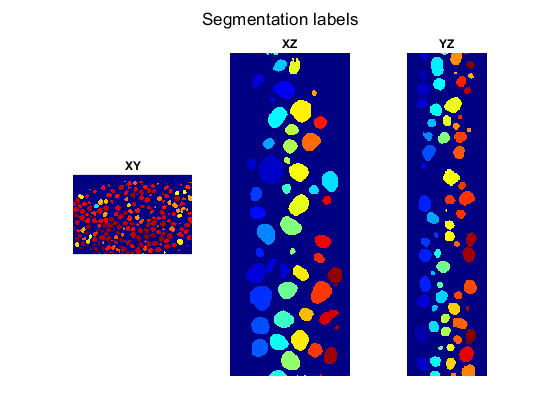

%% Kmeans clustering for pixels and component connecting to obtain the particle labels
StackProb = uint16(permute(StackXY, [2 3 1]) + permute(StackXZ, [3 2 1]) + StackYZ); % fusion all possibilities

StackProb2=imresize3(StackProb,0.25); % resize the stack to save memory
% StackProb2 = StackProb; % original stack size

Clusters = kmeans([StackProb2(:)],5); % pixel clustering based on the fused probability map
C = reshape(Clusters, size(StackProb2));
Label = bwlabeln(C-1); % connected components to generate the particle labels, background set to be 0
figure; subplot(1,3,1); imshow(Label(:,:,100),[]); title('XY')
subplot(1,3,2); imshow(squeeze(Label(:,100,:)),[]); title('XZ')
subplot(1,3,3); imshow(squeeze(Label(100,:,:)),[]);  title('YZ')
colormap('jet'); 
sgtitle('Segmentation labels')